# Muestreo

## A lazo abierto

#### Obtener la función de transferencia continua G(s)

G=zpk(-10,[-3 0],10)

G =
 
  10 (s+10)
  ---------
   s (s+3)
 
Continuous-time zero/pole/gain model.



Tm=4;

#### Hallar la FT discreta de lazo abierto Gd(s) del sistema de la figura con Z0H a la entrada y el tiempo de muestreo asignado Tm

Gd=c2d(G,Tm,'zoh')

Gd =
 
  125.56 (z+0.06194)
  -------------------
  (z-1) (z-6.144e-06)
 
Sample time: 4 seconds
Discrete-time zero/pole/gain model.



#### Dibujar el mapa de polos y ceros del sistema continuo y el discreto

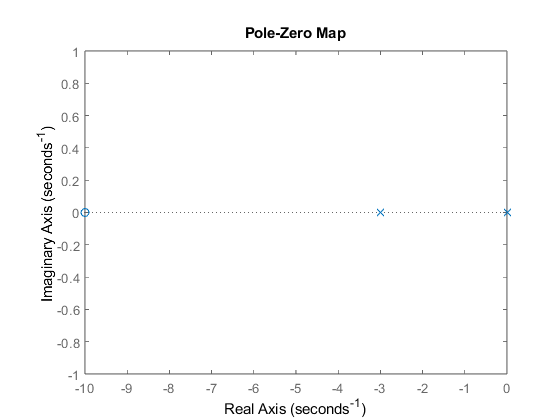

pzmap(G)

pole(G)

ans =     -3
     0


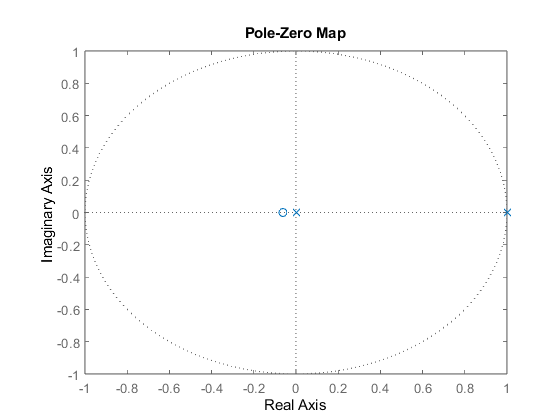

pzmap(Gd)

pole(Gd)

ans =     1.0000
    0.0000


#### ¿Qué ocurre con el mapa si se multiplica por 10 el periodo de muestreo?

Gd1 =
 
  1325.6 (z+0.005868)
  -------------------
        z (z-1)
 
Sample time: 40 seconds
Discrete-time zero/pole/gain model.



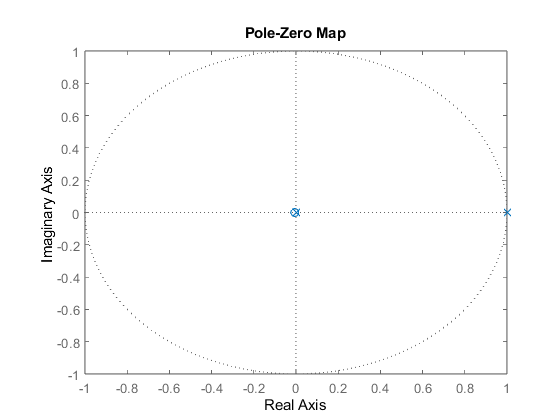

Gd1=c2d(G,10*Tm,'zoh'),pzmap(Gd1)

Se puede observar que al multiplicar 10 veces el tiempo de muestreo el segundo polo se acerca a un retardo puro mas integrador. Esto significa que estamos submuestreando la señal. 

#### Obtener la respuesta al escalon del sistema discreto y determinar si es estable

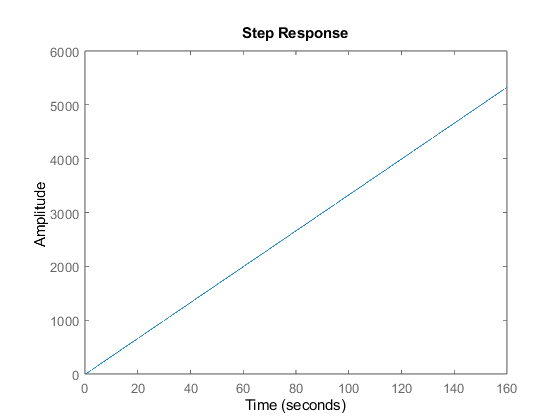

step(G)

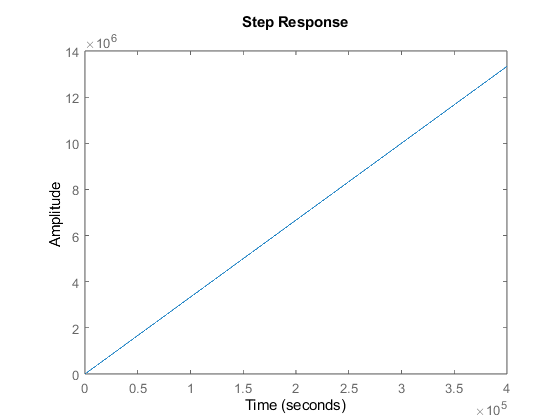

step(Gd)

Podemos observar que el sistema es inestable, lo cual es coincidente con el integrador puro en el sistema discreto.

## Sistema discreto

#### Determinar el tipo de sistema

Examinando la función de lazo abierto llegamos a la conclusion de que el sistema Gd es de tipo 1, ya que tenemos un solo integrador puro.

Gd

Gd =
 
  125.56 (z+0.06194)
  -------------------
  (z-1) (z-6.144e-06)
 
Sample time: 4 seconds
Discrete-time zero/pole/gain model.



#### Determinar la constante de error de posición Kp y el error ante un escalon y verificar mediante respuesta al escalon de lazo cerrado del sistema discreto como se muestra

Kp=dcgain(Gd)

Kp = Inf

F=feedback(Gd,1)

F =
 
   125.56 (z+0.06194)
  ---------------------
  (z+0.06247) (z+124.5)
 
Sample time: 4 seconds
Discrete-time zero/pole/gain model.



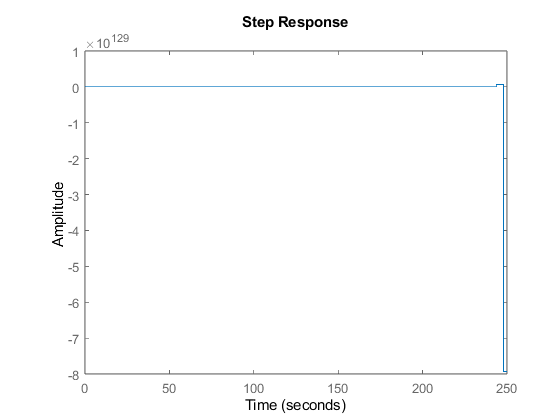

step(F)

El error debido a una entrada escalon es nulo, puesto que se cumple que Kp tiende al infinito (el sistema es tipo 1)

#### Verificar error ante una rampa de entrada, ¿Converge o diverge? Explicar la causa

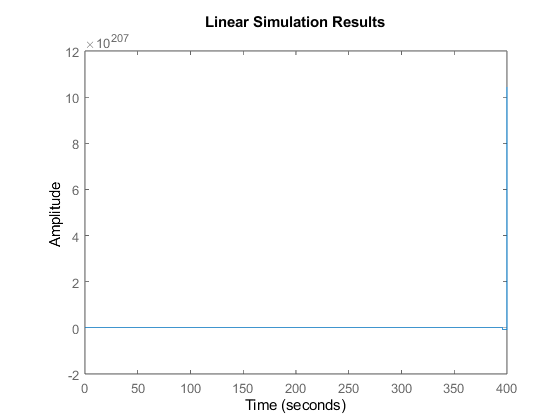

t=0:Tm:100*Tm; % genera rampa
lsim(F,t,t)

El sistema diverge. Esto es debido al tipo de sistema. Para que exista convergencia ante una rampa de entrada el sistema debe ser mínimo 

## A lazo cerrado con realimentación unitaria 

#### Graficar el lugar de raíces del sistema continuo G(s) y del discreto Gd(s)  indicando las ganancias criticas de estabilidad (si las hubiera)

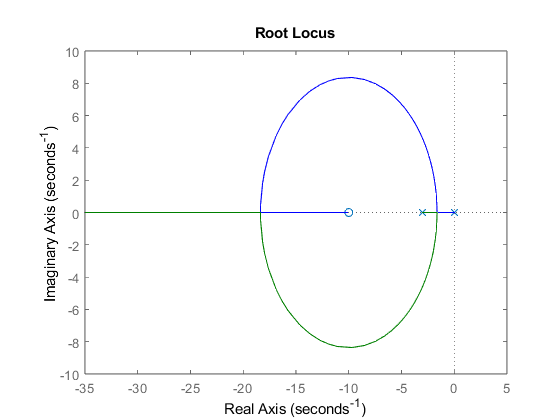

rlocus(G)

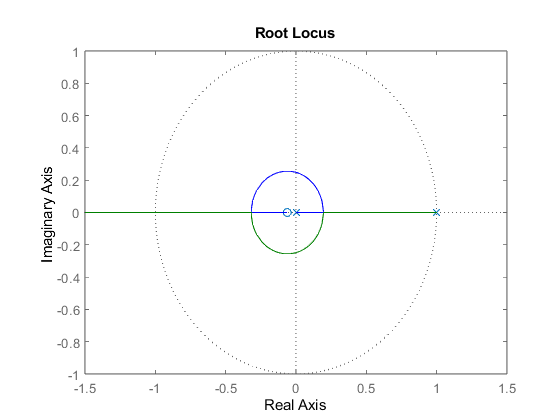

rlocus(Gd)

#### ¿ Que ocurre con la estabilidad relativa si se aumenta 10 veces el tiempo de muestreo original ? 

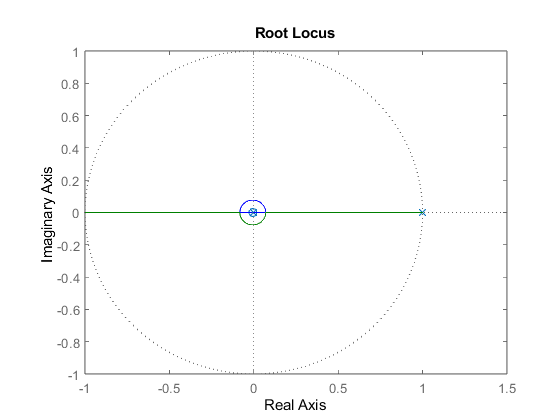

rlocus(Gd1)